clear all; close all; clc
n=2;
q_A=sym('q_A_',[n,1],'real')

$$q\_A = \left(\begin{array}{c} q_{A,1}\\ q_{A,2} \end{array}\right)$$

q_B=sym('q_B_',[n,1],'real')

$$q\_B = \left(\begin{array}{c} q_{B,1}\\ q_{B,2} \end{array}\right)$$

d_0=norm(q_A-q_B)

$$d\_0 = \sqrt{{\left|q_{A,1}-q_{B,1}\right|}^{2}+{\left|q_{A,2}-q_{B,2}\right|}^{2}}$$

q_range=(-6*pi:0.1:6*pi)+0*pi;
q_A_=[q_range+0*pi;zeros(size(q_range))];
q_B_=[zeros(2,size(q_range,2))];
difqab=mod(q_A_-q_B_,2*pi);
delta_=min(abs(difqab),2*pi-abs(difqab))

delta_ =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.0832    2.9832    2.8832    2.7832    2.6832    2.5832    2.4832    2.3832    2.2832    2.1832    2.0832    1.9832    1.8832    1.7832    1.6832    1.5832    1.4832    1.3832
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

d1_=sqrt(sum(delta_.^2))

d1_ =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.0832    2.9832    2.8832    2.7832    2.6832    2.5832    2.4832    2.3832    2.2832    2.1832    2.0832    1.9832    1.8832    1.7832    1.6832    1.5832    1.4832    1.3832


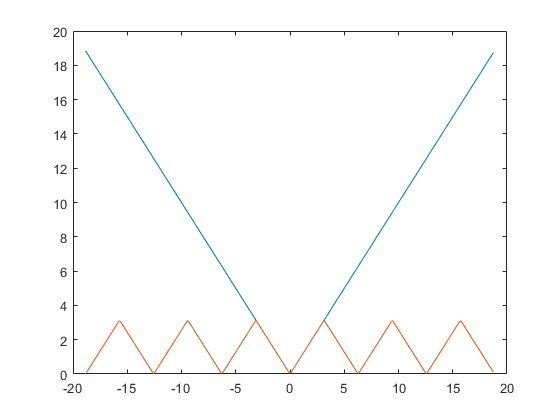

for qi=1:size(q_range,2)
    d_plot(qi)=norm(q_A_(:,qi)-q_B_(:,qi));
end
figure(1)
plot(q_range,d_plot)
hold on
plot(q_range,d1_)

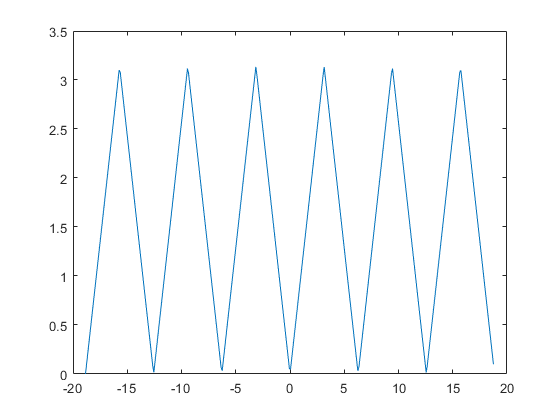

figure(2)
% plot(q_range,difqab(1,:))
% hold on
% plot(q_range,2*pi-difqab(1,:))
% 
% hold on
plot(q_range,delta_(1,:))

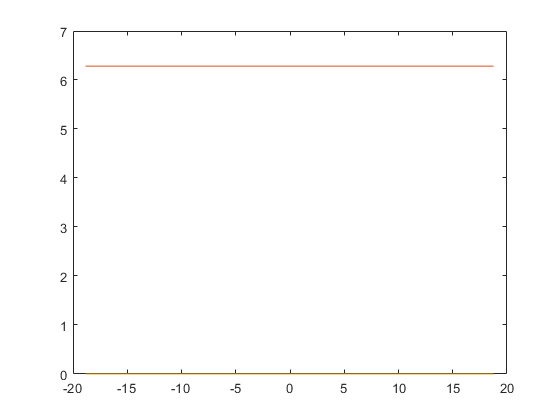


figure(3)
plot(q_range,difqab(2,:))
hold on
plot(q_range,2*pi-difqab(2,:))
hold on
plot(q_range,delta_(2,:))